% Header

# Polyfit

- **C = polyfit(**[**x**](https://localhost:31515/static/help/matlab/ref/polyfit.html?searchHighlight=polyfit&searchResultIndex=1#bue6sxq-1-x)**,**[**y**](https://localhost:31515/static/help/matlab/ref/polyfit.html?searchHighlight=polyfit&searchResultIndex=1#bue6sxq-1-y)**,**[**n**](https://localhost:31515/static/help/matlab/ref/polyfit.html?searchHighlight=polyfit&searchResultIndex=1#bue6sxq-1-n)**)** returns the coefficients for a polynomial of degree n that is a best fit (in a least-squares sense) for the data in x and y. The coefficients in C are in descending powers, and the length of C is n+1.

In ENGR 1410, we limit ourselves to **FIRST ORDER MODELS **or models that can be transformed into first order models. Therefore n will always be 1, i.e., **C = polyfit(**[**x**](https://localhost:31515/static/help/matlab/ref/polyfit.html?searchHighlight=polyfit&searchResultIndex=1#bue6sxq-1-x)**,**[**y**](https://localhost:31515/static/help/matlab/ref/polyfit.html?searchHighlight=polyfit&searchResultIndex=1#bue6sxq-1-y)**,1) **

## Text

% text( xloc, yloc, 'text')

## Linear Functions ($y=m\;x\;+b$)

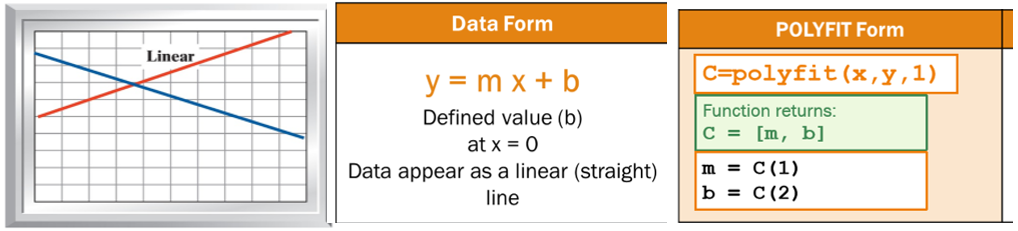

% % Linear model: fit/create data set
%     C = polyfit(x,y,1); 
%     m = C(1); 
%     b = C(2); 
%     Xpf = minVal:increment:maxVal;
%     Ypf = m * Xpf + b;

### Example L1

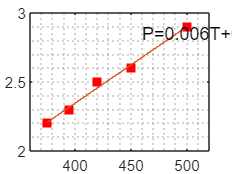

clear
clc
close all

% Variables
% T = temperature [K] -- Independent 
% P = Pressure [atm]  -- Dependent   

% Enter experimental data - Assume ideal gas law: PV = nRT
T = [375 395 420 450 500];	% Temperature [K] -independent
P = [2.2 2.3 2.5 2.6 2.9];	% Pressure [atm] -dependent

% Create graph of experimental data
figure('Color','w');
plot(T,P,'sr','MarkerFaceColor','r');hold on;
axis([360 520 2 3])
% Determine model parameters
% C = Results of POLYFIT function [m, b]
C=polyfit(T,P,1);
m=C(1);
b=C(2);

% Create theoretical data series with model results
% For variable names, __pf = theoretical model
X=T(1):20:T(end);
Y=m*X+b;


% Add theoretical data series to graph
plot(X,Y);
grid minor;

% Add trendline text to graph
% TE = trendline equation text
text(460,2.85,sprintf('P=%0.3fT+%0.2f',m,b));


% Calculate density - Assume ideal gas law: PV = nRT
R   = 0.08206;  % ideal gas constant [atm-L/mol-K]
gas = {'Oxygen (O_2)' 32; %MW=m/n
    'Air' 29;
    'Nitrogen (N_2)' 28};
MW=gas(:,2)

MW = 3×1 cell array
    {[32]}
    {[29]}
    {[28]}


rho=[]


rho =

     []



for kk=1:length(MW)
rho(kk,1)=m*MW{kk}/R;
end

### `Example L2`

**BEAM** represents fictional experimental data of Width (W) [mm] in column 1 and Mass (m) [g] in column 2. 

Create a proper plot of the experimental data (Mass as a function of width); and display a linear model for widths ranging from 1 to 20 millimeters.

clear
close all
clc
 
BEAM =[5,178; 7,231; 9,285; 12,366; 17,500];

Width=BEAM(:,1) %x

Width =      5
     7
     9
    12
    17


Mass=BEAM(:,2) %y

Mass =    178
   231
   285
   366
   500


plot(Width,Mass,'sr','MarkerFaceColor','r')
grid on;
C=polyfit(Width,Mass,1)

C =    26.8636   43.3636


m=C(1)

m = 26.8636

b=C(2)

b = 43.3636

Xpf=5:20

Xpf =      5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20


ypf=m*Xpf+b

ypf =   177.6818  204.5455  231.4091  258.2727  285.1364  312.0000  338.8636  365.7273  392.5909  419.4545  446.3182  473.1818  500.0455  526.9091  553.7727  580.6364


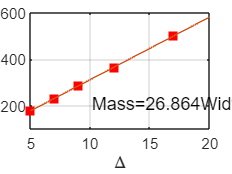

hold on
plot(Xpf,ypf)
xlabel('\Delta')
text(10,200,sprintf('Mass=%0.3fWidth+%0.2f \\Delta',m,b)); %special characters only aplicalbe to sprintf

## Quadratric - 2nd order polynomial

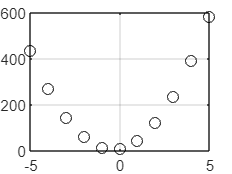

clear
close all
clc

hold off
x = -5:5;
y = 20*x.^2 + 15*x + 10;

plot(x,y,'ok')
grid on


C=polyfit(x,y,2)

C =    20.0000   15.0000   10.0000


## Power Functions ($y=bx^m$)

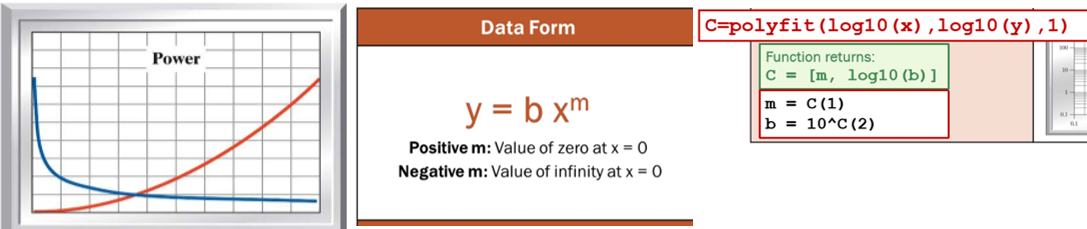

% Power model: fit / create data set 
%     C = polyfit(log10(x),log10(y),1); % logbase 10
%     m = C(1); 
%     b = 10^C(2); 
%     Xpf = minVal:increment:maxVal;d
%     Ypf = b * Xpf .^ m;   % ** for m ~= 1 need dot operator **

### Example P1

clear
clc
close all

% Variables
% R = radius [cm]
% V = volume, cylinder [cubic cm]

% Enter experimental data
R = [0.5 1 1.25 1.5 2];		% Radius [cm] -- independent variable
V = [3 13 20 28 50];		% Volume [cubic cm] -- dependent variable

% Create graph of experimental data
plot(R,V, 'sr','MarkerFaceColor','r')
hold on;
% Determine model parameters

% C = Results of POLYFIT function [m, b]

C=polyfit(log10(R),log10(V),1)

C =     2.0270    1.0970



% Create theoretical data series with model results
CMM=0:.01:2

CMM =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


m=C(1)

m = 2.0270

b=10.^(C(2))

b = 12.5018

% For variable names, __pf = theoretical model

Y=b*CMM.^m

Y =          0    0.0011    0.0045    0.0102    0.0183    0.0288    0.0417    0.0570    0.0747    0.0949    0.1175    0.1425    0.1700    0.2000    0.2324    0.2673    0.3046    0.3444    0.3868    0.4315    0.4788    0.5286    0.5809    0.6356    0.6929    0.7527    0.8150    0.8798    0.9471    1.0169    1.0892    1.1641    1.2414    1.3213    1.4038    1.4887    1.5762    1.6662    1.7588    1.8538    1.9515    2.0516    2.1543    2.2596    2.3673    2.4777    2.5905    2.7060    2.8239    2.9445


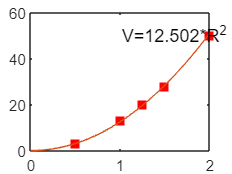

plot(CMM,Y)
% Add theoretical data series to graph


% Add trendline text to graph
% TE = trendline equation text

text(1,50,sprintf('V=%0.3f*R^%0.0f',b,m))

% Calculate cylinder length

L=b/pi

L = 3.9794

### Example P2

Assume the following data is available, in format [Length (L) [in], frequency [Hz]] for a pendulum.

Create a proper plot of the experimental data  (Frequency as a function of Length); and display a power model from a length of 5 to 30 inches.  

clear
close all
clc

data = table({'V01'; 'V02'; 'V03'; 'V04'}, ...
             [8; 15; 18; 24], ...
             [1.11; 0.81; 0.75; 0.64]);
data.Properties.VariableNames = {'Trial', 'L', 'f'}

data = 4×3 table
     Trial     L      f  
    _______    __    ____

    {'V01'}     8    1.11
    {'V02'}    15    0.81
    {'V03'}    18    0.75
    {'V04'}    24    0.64


## Exponential Functions ($y=b\;e^{\textrm{mx}}$)

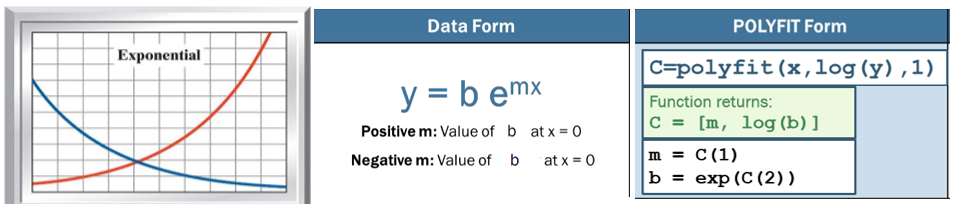

% % Exponential model: fit/create data set
%     C = polyfit(x,log(y),1); % nat. log
%     m = C(1); 
%     b = exp(C(2)); 
%     Xpf = minVal:increment:maxVal;
%     Ypf = b * exp(m * Xpf);

### Example E1

clear
clc
close all

% Variables
% t = time [s]
% V = voltage [V]

% Enter experimental data
t = [1 5 15 20 30];		% time [s]  -- independent variable
V = [18.1 12.1 4.5 2.75 1];	% voltage [V] -- dependent variable

% Create graph of experimental data
plot(t,V,'sr')

% Determine model parameters
% C = Results of POLYFIT function [m, b]
C=polyfit(t,log(V),1)

C =    -0.0997    2.9961


m=C(1)

m = -0.0997

b=exp(C(2))

b = 20.0067

% Create theoretical data series with model results
% For variable names, __pf = theoretical model
Xpf=0:30

Xpf =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30


ypf=b * exp(m * Xpf)

ypf =    20.0067   18.1090   16.3914   14.8366   13.4294   12.1556   11.0026    9.9590    9.0144    8.1594    7.3855    6.6849    6.0509    5.4769    4.9574    4.4872    4.0616    3.6764    3.3277    3.0120    2.7263    2.4677    2.2337    2.0218    1.8300    1.6565    1.4993    1.3571    1.2284    1.1119    1.0064


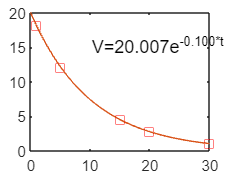

hold on
plot(Xpf, ypf)
% Add theoretical data series to graph


% Add trendline text to graph
% TE = trendline equation text
text(10,15,sprintf('V=%0.3fe^{%0.3f*t}',b,m))


% Calculate RC time constant (V = Vo e(-t/RC))
tau=-1/m
